# 1) Carga de datos

En primer lugar cargamos los datos que vamos a usar.  Ten en cuenta que una vez cargados, deberán seperarse en dos conjuntos diferente: matriz de diseño en la variable "x" y etiquetas en la varible "y". 

load fisheriris
x = meas;
y = categorical(species); % Cambiamos el tipo de dato. Ahora "y" es de tipo categorico
labels = categories(y); % Imprimimos las categorias
disp(labels) 

    'setosa'
    'versicolor'
    'virginica'



% Para evitar sorpresas imprimirmos los tipos de datos.
disp(class(x)) 

double


disp(class(y))

categorical


# 2) Examinamos los datos: ¿Tenemos razones a priori de que son conjuntos separables?

En todo trabajo de minería de datos, es importante saber como son los datos, que tipo de relaciones existen entre ellos. La mejor forma de lograr este objetivo es a través de su visualización. Es importante tener en cuenta que no siempre es posible, ya que esto dependerá del tamaño de características. Un espacio con muchas características presentará muchas dificultades a la hora de la visualización. En este caso, caso tenemos un espacio con 4 características (decirlas). Cada muestra está clasificada en "setosa", "versicolor", "virginica".




%% Explicacion estadistica de los datos
figure(1)
x(1:10,:) % Visualizamos las 10 primeras muestras

ans =     5.1000    3.5000    1.4000    0.2000
    4.9000    3.0000    1.4000    0.2000
    4.7000    3.2000    1.3000    0.2000
    4.6000    3.1000    1.5000    0.2000
    5.0000    3.6000    1.4000    0.2000
    5.4000    3.9000    1.7000    0.4000
    4.6000    3.4000    1.4000    0.3000
    5.0000    3.4000    1.5000    0.2000
    4.4000    2.9000    1.4000    0.2000
    4.9000    3.1000    1.5000    0.1000


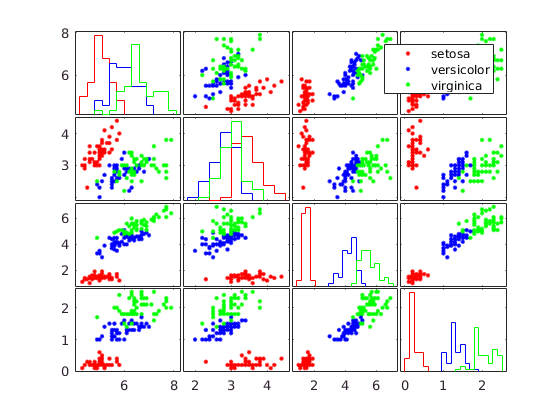

gplotmatrix(x, [], species, ['r', 'b', 'g']) % Hacemos un plot enfrentando a todas las características

# 3) Redes neuronales: algoritmo de clasificación

## 3.1) En primer lugar tenemos que crear la red. 

Lo primero de todo será crear la estructura "red neuronal". Mas adelante iremos incorporando 

hiddenLayerSize = 10;
trainFcn = 'trainscg' % probar con varias

trainFcn = 'trainscg'

my_net = patternnet(hiddenLayerSize, trainFcn);
view(my_net) % Visualizamos la red que hemos creado



## 3.2) Division del conjunto de datos

Para poder llevar a cabo un proceso de clasificación necesitmos dividir el conjunto de datos en dos subconjuntos. El subconjunto de datos usado para el entrenamiento de la red neuronal se suele denominar "conjunto de entrenamiento",  y el subconjunto de los datos usado para realizar el test, "conjunto test".  Por otro lado, hay que tener en cuenta que el conjunto de test es un "bien muy preciado", ya que permitirá evaluar el rendimiento de tu clasificador, con lo cual no podrás utilizarlo hasta que tengas la red preparada. Esto implica, que todas las modificaciones que hagas en los parámetros de la red, no podrás probarlo en tu test, ya que sin darte cuenta estarías haciendo trampas. El motivo de esto, es que estarías usando ajustando los parámetros de tu red, a los resultados que obtienes en el test. Por este motivo se creará otro subconjunto de datos denominado "Conjunto de validación". 

## En resumen: 

- Conjunto de entrenamiento (Train Set): Con este conjunto se entrenará la red neuronal

- Conjunto de validacion (Validation Set): Con este conjunto se realizará el ajuste (tunning) de los parámetros de la red

- Conjunto de test (Test Set): Cuando ya lo tengas todos listo y creas que tu red esta ajustada para dar el mejor rendimiento posible, evaluarás su rendimiento comparándola con este conjunto.